close all; clear; clc;

# Regen Braking Plots

**file name**: 

**keywords:** 

**date of test:** date

**file created by:** 20190513, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

RBoff = xlsread('Master_Spreadsheet_RBoff_20190513.xls');
RBon_2b = xlsread('MEGA_2b_RBon.xlsx');
RBon_3b = xlsread('MEGA_3b_RBon.xlsx');
RBon = xlsread('MEGA_RBon.xlsx');

## Assigning variables

st_RBoff = RBoff(:,22);
dRPM_RBoff = RBoff(:,27);
dPin_RBoff = RBoff(:, 28);

st_RBon = RBon(:,22);
dRPM_RBon = RBon(:,27);
dPin_RBon = RBon(:, 28);

st_RBon_2b = RBon_2b(:,22);
st_RBon_3b = RBon_3b(:,22);
dRPM_RBon_2b = RBon_2b(:,27);
dPin_RBon_2b = RBon_2b(:, 28);
dRPM_RBon_3b = RBon_3b(:,27);
dPin_RBon_3b = RBon_3b(:, 28);

## Plots

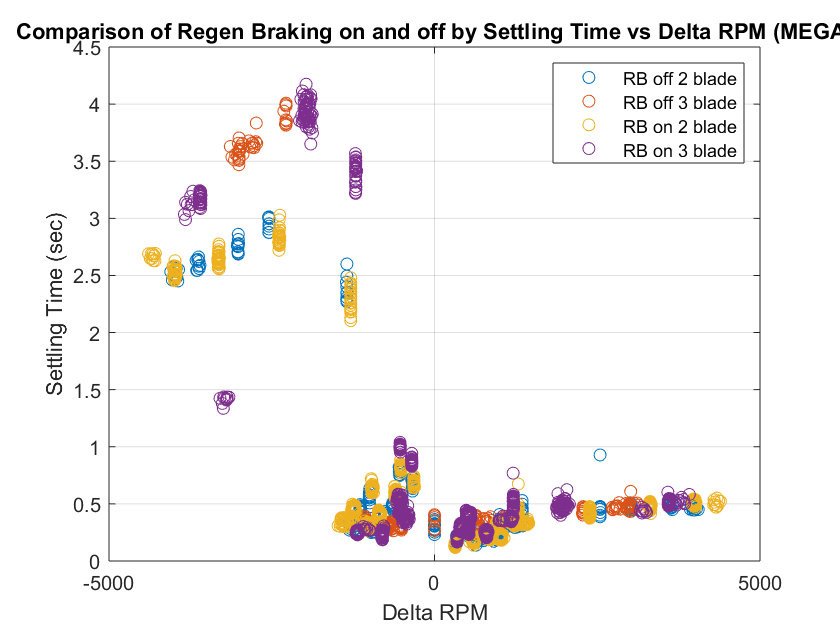

figure(1)
plot(dRPM_RBoff(1:315), st_RBoff(1:315), 'o', dRPM_RBoff(316:end), st_RBoff(316:end), 'o',...
    dRPM_RBon_2b, st_RBon_2b, 'o', dRPM_RBon_3b, st_RBon_3b, 'o');
legend('RB off 2 blade', 'RB off 3 blade', 'RB on 2 blade', 'RB on 3 blade');
title('Comparison of Regen Braking on and off by Settling Time vs Delta RPM (MEGA)');
ylabel('Settling Time (sec)'); xlabel('Delta RPM'); grid on;

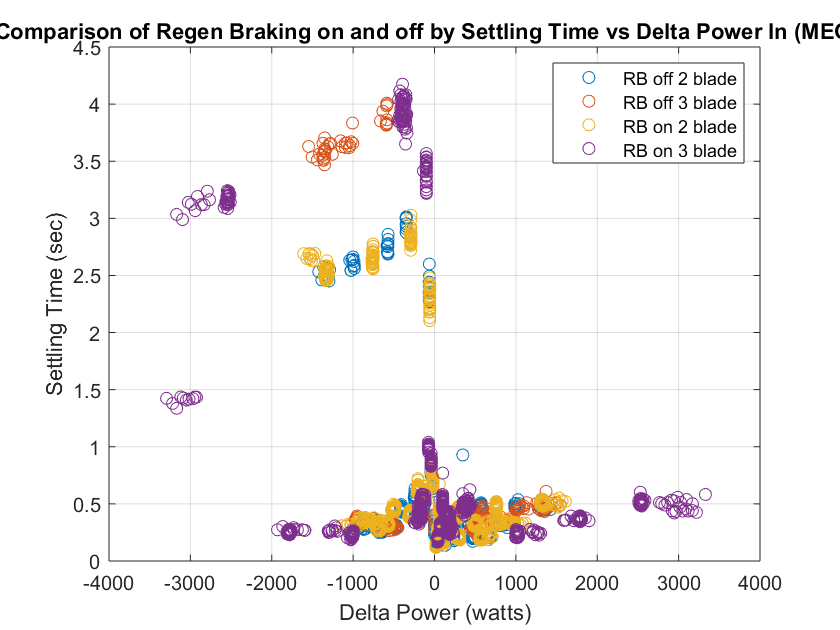


figure(2)
plot(dPin_RBoff(1:315), st_RBoff(1:315), 'o', dPin_RBoff(316:end), st_RBoff(316:end), 'o',...
    dPin_RBon_2b, st_RBon_2b, 'o', dPin_RBon_3b, st_RBon_3b, 'o');
legend('RB off 2 blade', 'RB off 3 blade', 'RB on 2 blade', 'RB on 3 blade');
title('Comparison of Regen Braking on and off by Settling Time vs Delta Power In (MEGA)');
ylabel('Settling Time (sec)'); xlabel('Delta Power (watts)'); grid on;

## Different view of data

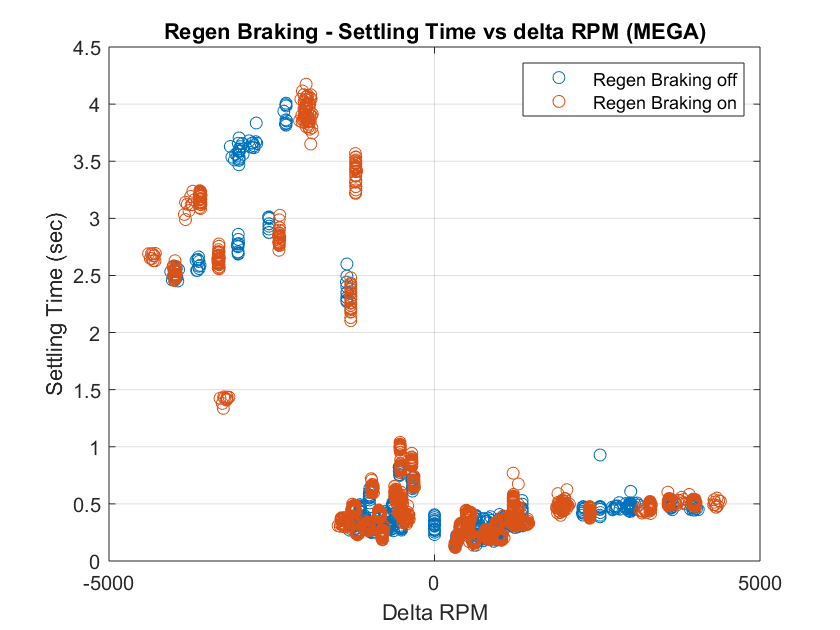

figure(3)
plot(dRPM_RBoff, st_RBoff, 'o',...
    dRPM_RBon, st_RBon, 'o');
legend('Regen Braking off', 'Regen Braking on'); ylabel('Settling Time (sec)');
xlabel('Delta RPM'); grid on;
title('Regen Braking - Settling Time vs delta RPM (MEGA)')

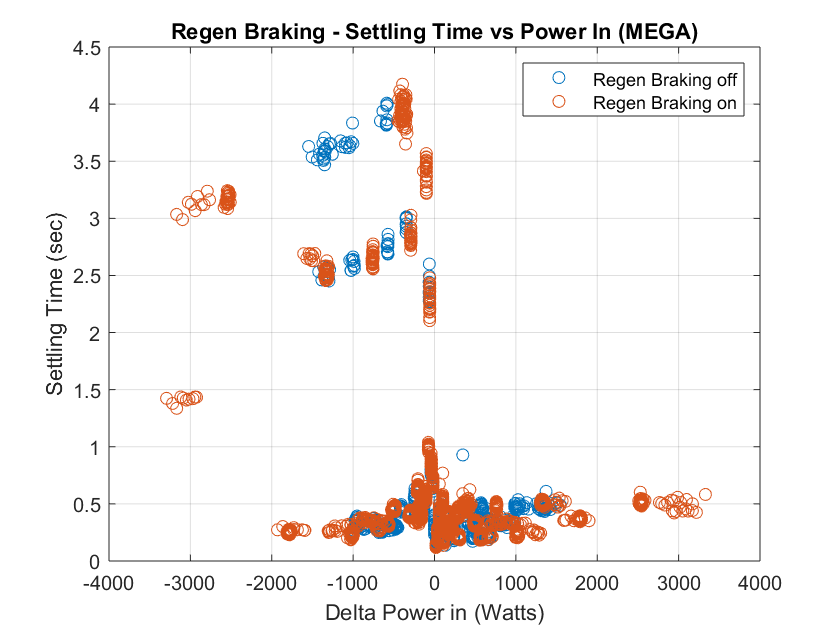


figure(4)
plot(dPin_RBoff, st_RBoff, 'o',...
    dPin_RBon, st_RBon, 'o');
legend('Regen Braking off', 'Regen Braking on'); ylabel('Settling Time (sec)');
xlabel('Delta Power in (Watts)'); grid on;
title('Regen Braking - Settling Time vs Power In (MEGA)')